% Figure 5 Gaussian Knockoffs Strategy Illustration
% requires MATLAB knockoff package by Stanford, available at https://github.com/msesia/knockoff-filter
close all;clearvars

## Triangular Distributions with Gaussian Copula

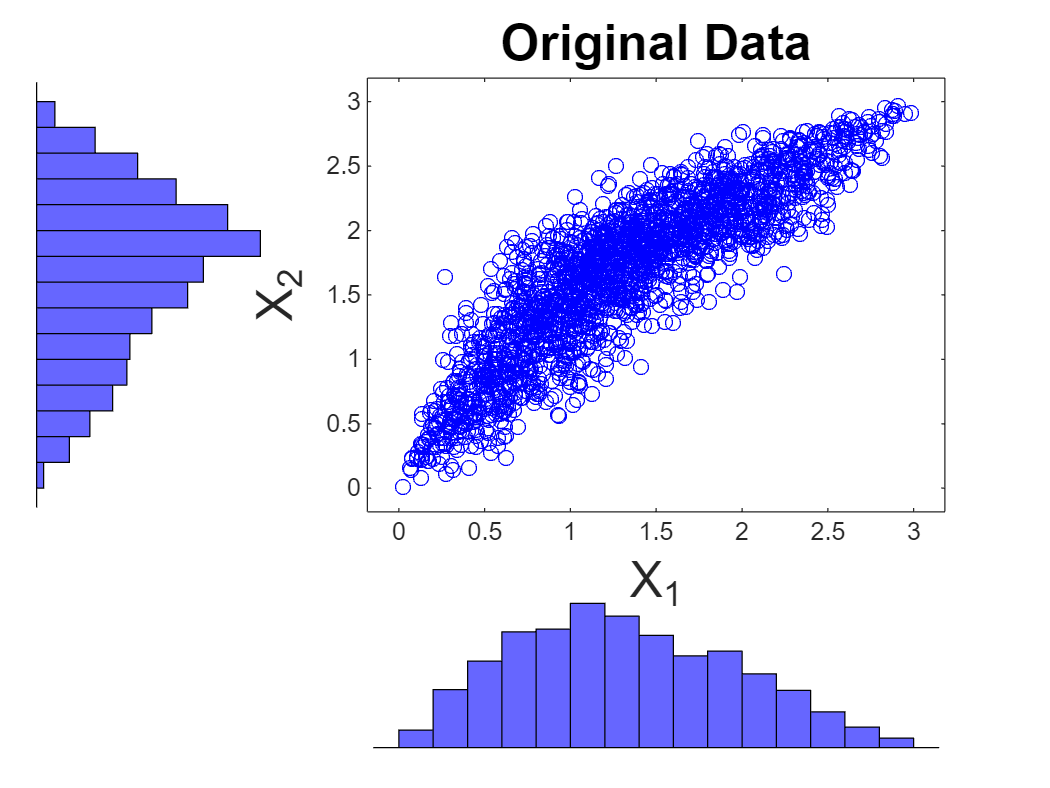


mypause=@()snapnow;
rng(1234)
n=2000;
u=rand(n,2);
x=iccorrelate([triinv(u(:,1),0,1,3),triinv(u(:,2),0,2,3)],[1,.9;.9,1]);
scatterhist(x(:,1),x(:,2),'Color','b');
title('Original Data','FontSize',20)
xlabel('X_1','FontSize',20)
ylabel('X_2','FontSize',20)

## Triangular Distributions with Gaussian Copula: Indeed

z=norminv(uniformer(x));
figure
h=scatterhist(z(:,1),z(:,2),'Color','b')

h =   1×3 Axes array:

    Axes    Axes    Axes


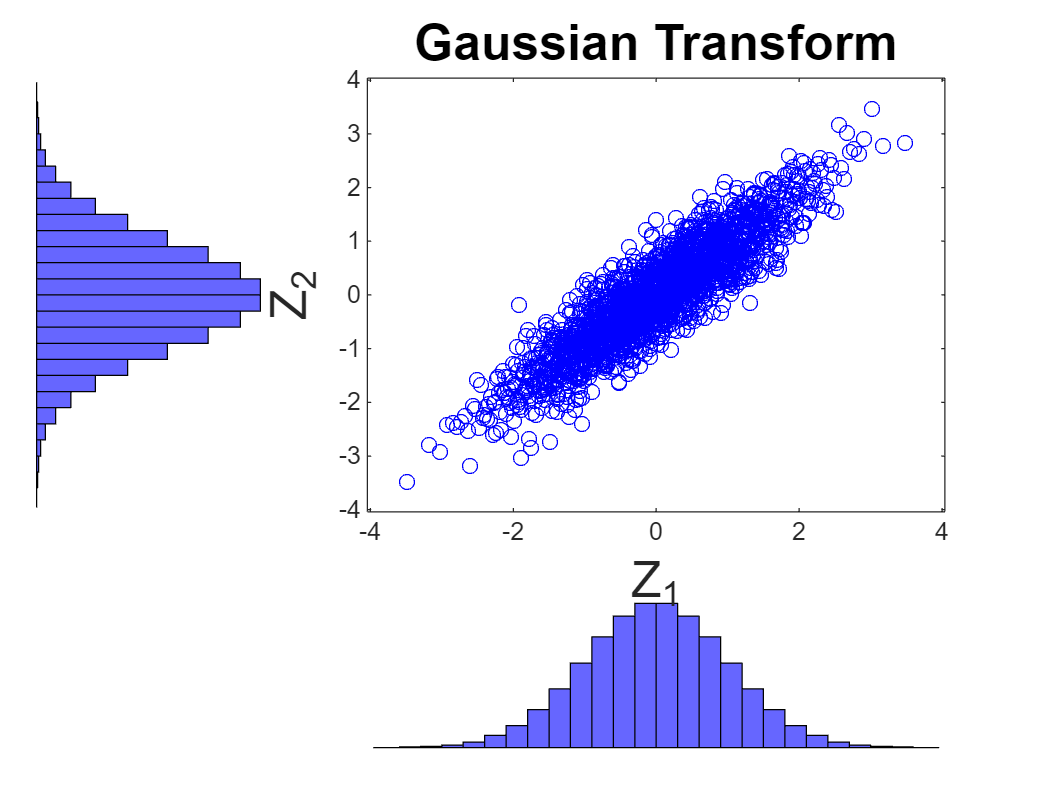

title('Gaussian Transform','FontSize',20)
xlabel('Z_1','FontSize',20)
ylabel('Z_2','FontSize',20)
axes(h(1))

%hold('on')
%plot([-3,3],[-3,+3]*.9,'r-','LineWidth',3)


## Generate Knockoffs in the Gaussian Space 

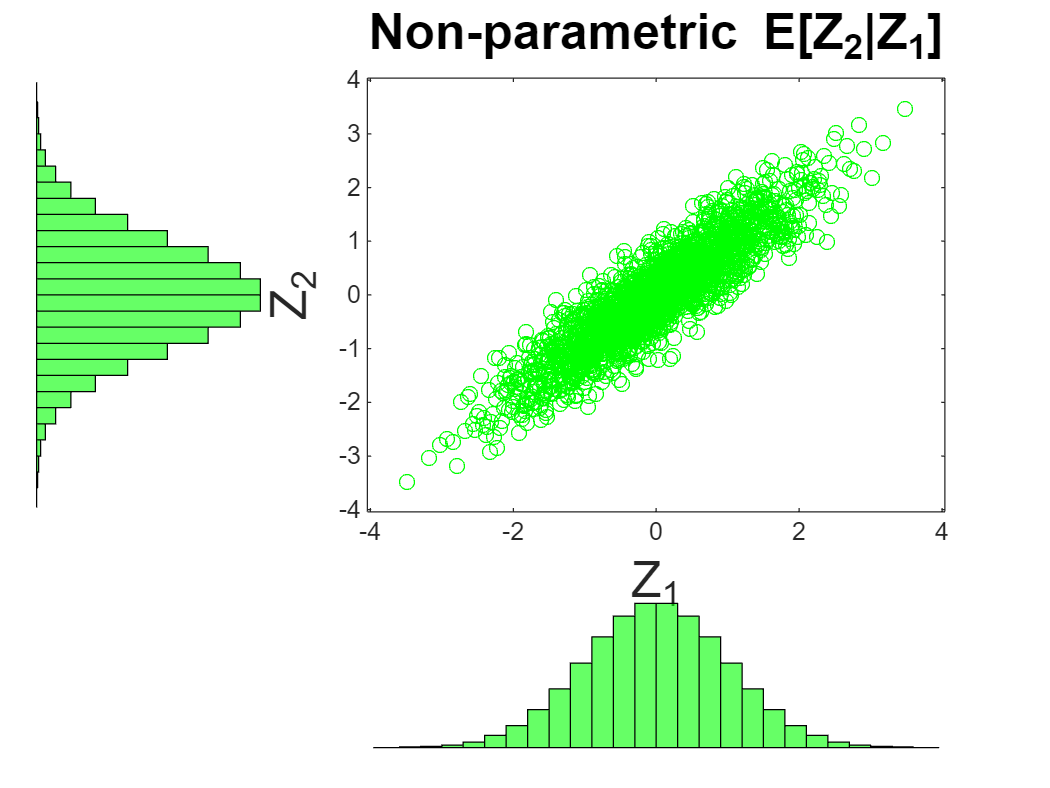

figure
%subplot(4,1,1)
[zp]=functionknockoffCandes(z);
% axes 1
scatterhist(z(:,1),zp(:,2),'Color','g');
title('Non-parametric E[Z_{2}|Z_{1}]','FontSize',20)
xlabel("Z_1",'FontSize',20)
ylabel("Z_2",'FontSize',20)

## Still Gaussian

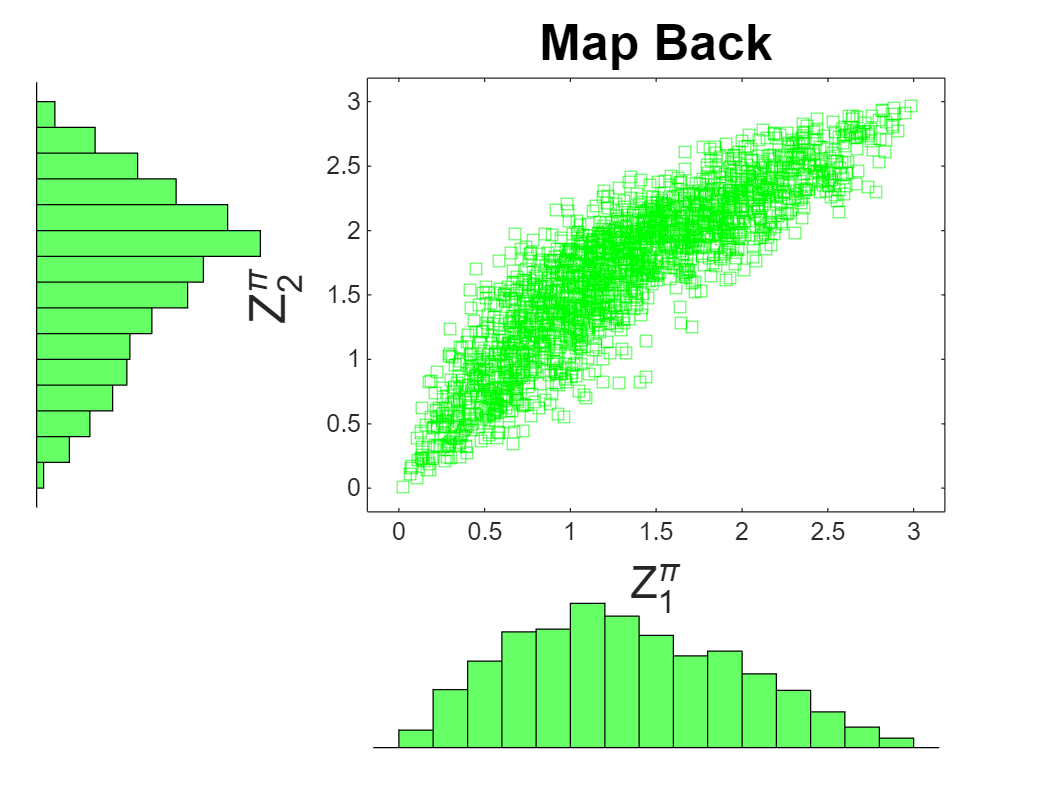


zz=[z(:,1) zp(:,2)];

%% Back to Original Distribution
xs=sort(x(:,2));
%scatterhist(x(:,1),xs(ceil(normcdf(zz(:,2))*length(x))),'Color','g') %wo interpolation
%pause
xx=[x(:,1),quantile(x(:,2),normcdf(zz(:,2)))];
scatterhist(x(:,1),xx(:,2),'Color','g','Marker','s') % with
title('Map Back','FontSize',20);
xlabel('Z_1^{\pi}','FontSize',18)
ylabel('Z_2^{\pi}','FontSize',20)

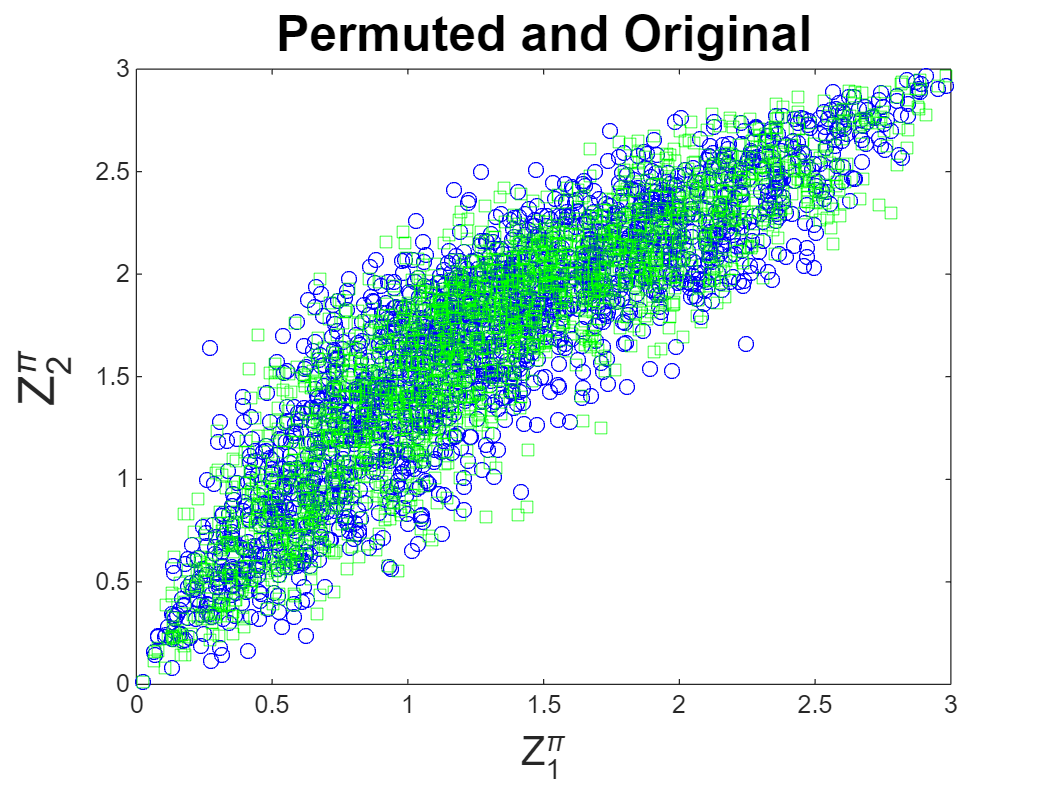


figure
plot(x(:,1),x(:,2),'bo',xx(:,1),xx(:,2),'gs')
title('Permuted and Original','FontSize',20);
xlabel('Z_1^{\pi}','FontSize',16)
ylabel('Z_2^{\pi}','FontSize',20)

## Knockoffs directly on data

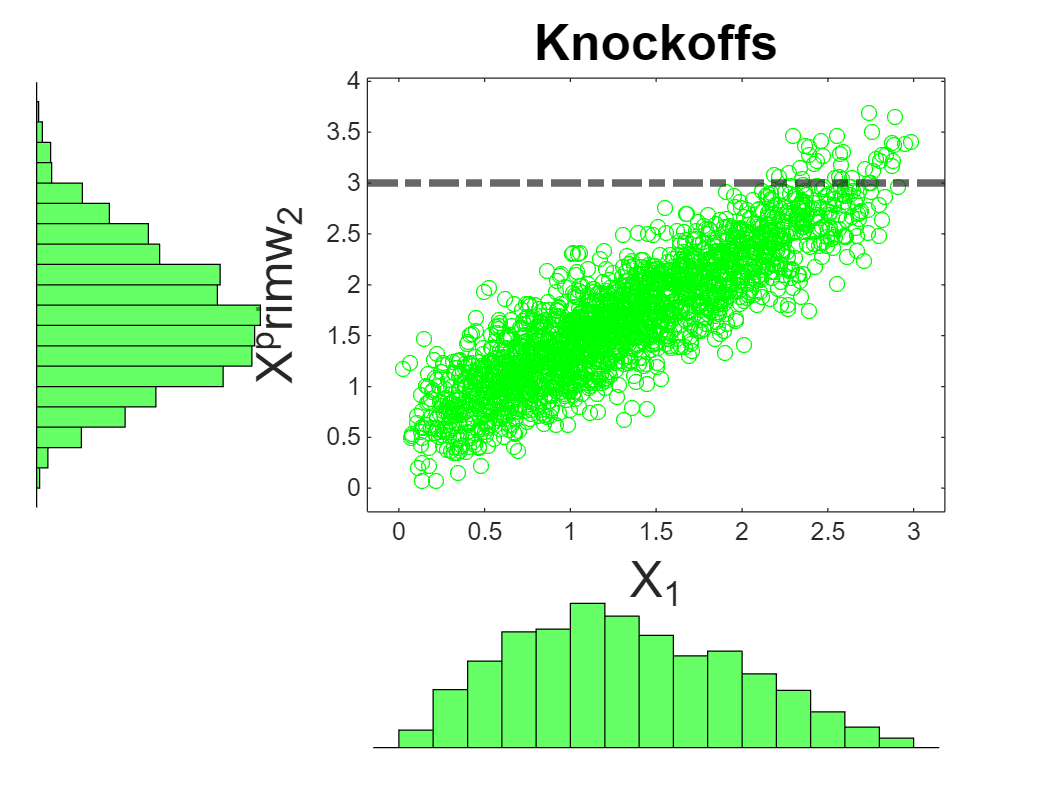

figure
%subplot(2,1,1)
[xp]=functionknockoffCandesNoTrafo(x);
% axes 1
scatterhist(x(:,1),xp(:,2),'Color','g');
yline(3,'-.','LineWidth',3)
title('Knockoffs','FontSize',20)
xlabel("X_1",'FontSize',20)
ylabel("X^primw_2",'FontSize',20)

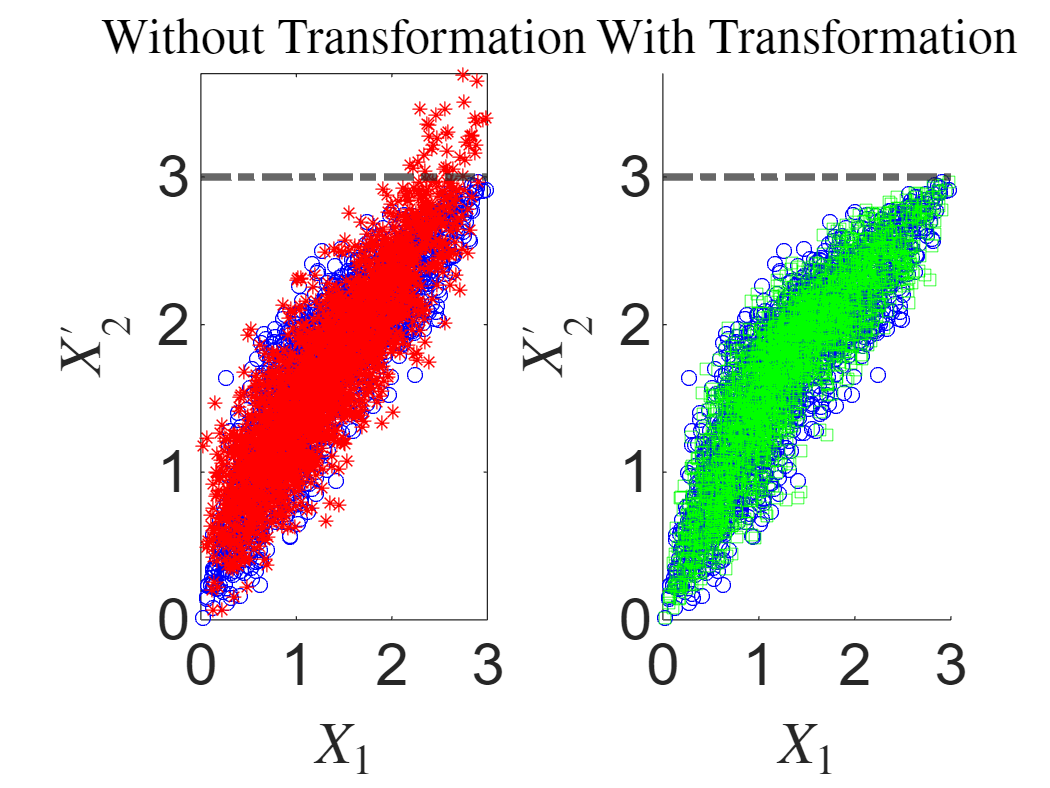

%Comparison to free permutations
% Just scatter
figure
subplot(1,2,1)
plot(x(:,1),x(:,2),'bo',x(:,1),xp(:,2),'r*')
xlim([0.00 3.00])
ylim([0.00 3.70])
yline(3,'-.','LineWidth',3)
set(gca,'FontSize',24)
title('Without Transformation','FontSize',20,'interpreter','latex')
xlabel('$X_1$','FontSize',24,'interpreter','latex')
ylabel('$X^\prime_2$','FontSize',24,'interpreter','latex')

subplot(1,2,2)
hold on
plot(x(:,1),x(:,2),'bo',x(:,1),xx(:,2),'gs')
xlim([0.00 3.00])
ylim([0.00 3.70])
yline(3,'-.','LineWidth',3)
%legend('Original ($\mathbf{X}$)','New ($\mathbf{X}^\prime)$','interpreter','latex','Fontsize',18)
set(gca,'FontSize',24)
title('With Transformation','FontSize',20,'interpreter','latex');
xlabel('$X_1$','FontSize',24,'interpreter','latex')
ylabel('$X_2^\prime$','FontSize',24,'interpreter','latex')

function [XprimeG]=functionknockoffCandes(X)
% KNOCKOFF Create a Model-X Knockoff sample using sequential conditional 
% independent pairs.
% [XPRIME]=KNOCKOFF(X) returns for the matrix X
% the knockoff sample XPRIME (under Gaussian copula assumptions).
% Key-value options are available

% Gaussian Transformation of the data
W=norminv(uniformer(X)); % or empcdf
W0=(W-mean(W))./std(W);
C=cov(W0);
% Creating the Knockoffs in the Gaussian space
W1=knockoffs.create(W0,'gaussian',zeros(1,size(X,2)),C);
if(nargin>1)
    XprimeG=W1;
else
% Coming back to original scale
Xsort=sort(X);
[~,indW]=sort(W1);
for j=1:size(X,2)
XprimeG(indW(:,j),j)=Xsort(:,j);
end
end
end
%% No Tranformation
function [XprimeG]=functionknockoffCandesNoTrafo(X)
% KNOCKOFF Create a Model-X Knockoff sample using sequential conditional 
% independent pairs.
% [XPRIME]=KNOCKOFF(X) returns for the matrix X
% the knockoff sample XPRIME (under Gaussian copula assumptions).
% Key-value options are available

% Gaussian Transformation of the data
%W=norminv(uniformer(X)); % or empcdf
W0=(X-mean(X))./std(X);
C=cov(W0);
% Creating the Knockoffs in the Gaussian space
W1=knockoffs.create(W0,'gaussian',zeros(1,size(X,2)),C);
    XprimeG=W1.*std(X)+mean(X);
end
